Received data formatting to matlab compatibility

clear all;

%%% This script is used to read the binary file produced by the DCA1000
%%% and Mmwave Studio
%%% Command to run in Matlab GUI - readDCA1000('<ADC capture bin file>')
% function [retVal] = readDCA1000(fileName)
%% global variables
% change based on sensor config
numADCBits = 16; % number of ADC bits per sample
numLanes = 4; % do not change. number of lanes is always 4 even if only 1 lane is used. unused lanes
isReal = 0; % set to 1 if real only data, 0 if complex dataare populated with 0 %% read file and convert to signed number
% read .bin file
fid = fopen('C:\Users\Anuradha\Desktop\AUT_Venture_Demo\Test_Data\Data1\adc_data.bin','r');
% DCA1000 should read in two's complement data
adcData = fread(fid, 'int16');
% if 12 or 14 bits ADC per sample compensate for sign extension 
if numADCBits ~= 16
    l_max = 2^(numADCBits-1)-1;
    adcData(adcData > l_max) = adcData(adcData > l_max) - 2^numADCBits;
end
fclose(fid);
%% organize data by LVDS lane
% for real only data
if isReal
    % reshape data based on one samples per LVDS lane
    adcData_reshaped = reshape(adcData,numLanes,[]);
    %for complex data
else
    % reshape and combine real and imaginary parts of complex number
    adcData_reshaped = reshape(adcData, numLanes*2, []);
    adcData = adcData_reshaped([1,2,3,4],:) + sqrt(-1)*adcData_reshaped([5,6,7,8],:);
end
%% return receiver data
retVal = adcData;

## Beamforming at receiver


% % Construct the receive array
c=3e8;
fc=77e9;
lambda=c/fc;
Ne = 4;
rxArray = phased.ULA('NumElements',Ne,...
    'ElementSpacing',lambda/2);
% Form forward-facing beam
beamformer = phased.PhaseShiftBeamformer('SensorArray',rxArray,...
    'PropagationSpeed',c,'OperatingFrequency',fc,'Direction',[0;0]);
% Beamform received data
Xbf = beamformer(retVal');
bf_data=Xbf';

## DC Offset correction

% % correct the signal through dc offset correction

%  for i = 1:Nrow
Bi = real(bf_data);
Bq = imag(bf_data);
Ar= sqrt(sum((Bi.^2) + (Bq.^2))) ;
fun = @(dc)(abs(sqrt((Bi - dc(1)).^2 + (Bq - dc(2)).^2 ) - dc(3)));
dc0 = [0,0,Ar];
options = optimoptions(@lsqnonlin,'Algorithm','levenberg-marquardt');
dcnew = lsqnonlin(fun,dc0,[],[],options);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


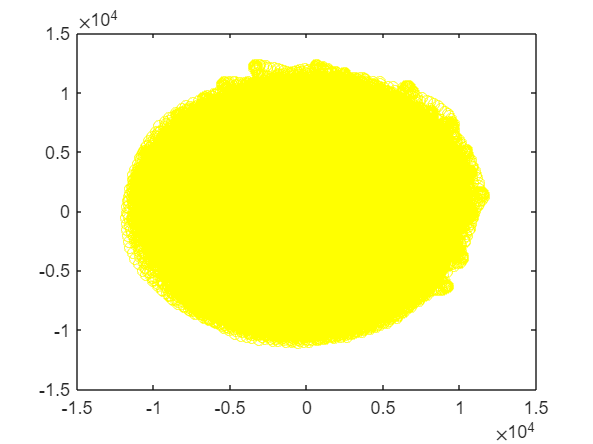

Bin = (Bi-dcnew(1,1));      % for hetrodyne architecture amplitude imabalnce is not needed
Bqn = (Bq-dcnew(1,2));

%  end

figure(1);clf
plot(Bq,Bi,'o', "Color",'y');

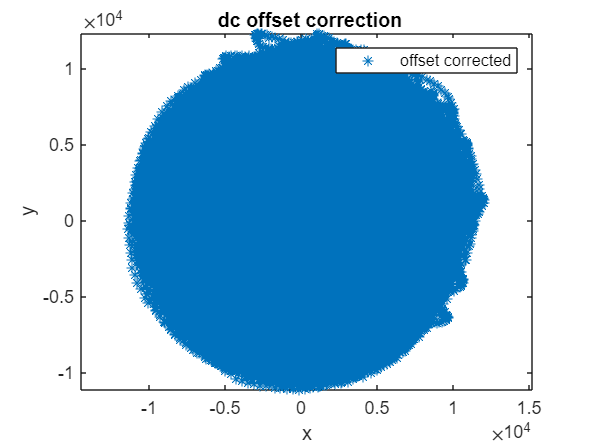

plot(Bqn,Bin,'*');
title(' dc offset correction')
legend('offset corrected')
xlabel x, ylabel y
axis equal


bf_signal_dccorrected = complex(Bin, Bqn);

# %Data Cube Formation


% no of chirps Nchirp
% no of samples in a chirp Nsample
% data cube formation
Nsample=128;
Nrow= round(length(bf_data)/Nsample); %2048
% Nrow=2048;
fs = 200;  % sampling frequency of signal :slow time sampling rate :
end_val = 0;
data_cube = complex(zeros(Nrow,Nsample));
data_cube_complete = complex(zeros(Nrow,Nsample));
for i = 1:Nrow
    init_val = end_val+1;
    end_val = Nsample*i;
    data_cube(i,:) = bf_data(1, init_val:end_val);
 data_cube_complete(i,:) = bf_signal_dccorrected(1, init_val:end_val);
end
data_cube_locs=diff(data_cube_complete);

## PHASE EXTRACTION: VITAL SIGNAL

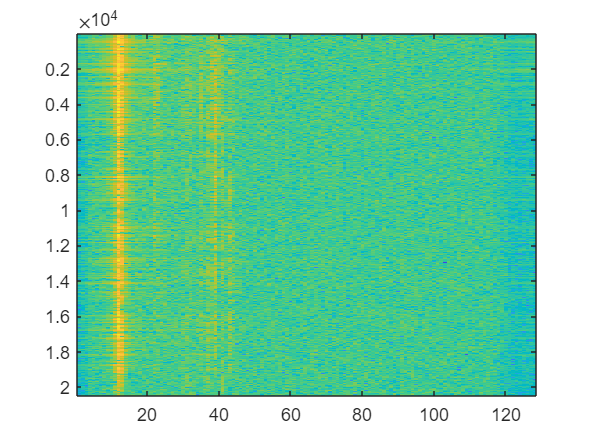

    range_slow_mat_locs = fft(data_cube_locs,Nsample,2); % range bin finding through fft on fast time smples
    figure(10);
    imagesc(mag2db(abs(range_slow_mat_locs)));

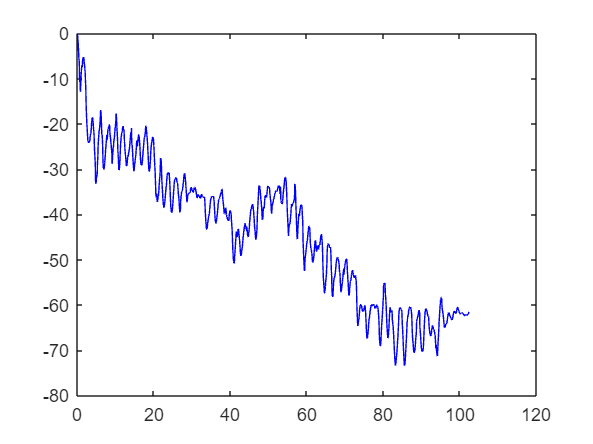

    pow_range =(abs(range_slow_mat_locs).^2);
    mean_pow_range = mean(pow_range);
    [pks1,locs1] = max(mean_pow_range(1,1:50));
%         locs1=14
    range_slow_mat = fft(data_cube_complete,Nsample,2); % range bin finding through fft on fast time smples
    signal_target=range_slow_mat(:,locs1);
    sig_i=real(signal_target);
    sig_q=imag(signal_target);
    nmer=zeros(Nrow,1);
    dnmer=zeros(Nrow,1);
    ph_term=zeros(Nrow,1);
    x_phase=zeros(Nrow,1);
    for k=2:Nrow
        nmer(k)=sig_i(k)*(sig_q(k)-sig_q(k-1))-(sig_i(k)-sig_i(k-1))*sig_q(k);
        dnmer(k)= sig_q(k)^2+sig_i(k)^2;
        ph_term(k)=nmer(k)/dnmer(k);
    end
    for n=2:Nrow
        x_phase(n)=sum(ph_term(2:n));
    end
   
    x_phase=downsample(x_phase,10);
    fs=fs/10;
    N = length(x_phase);
    t = (0:N-1)/fs;         % time axis
    figure(5);clf
    plot(t,x_phase,'b')